# **Metoda ekspansji**

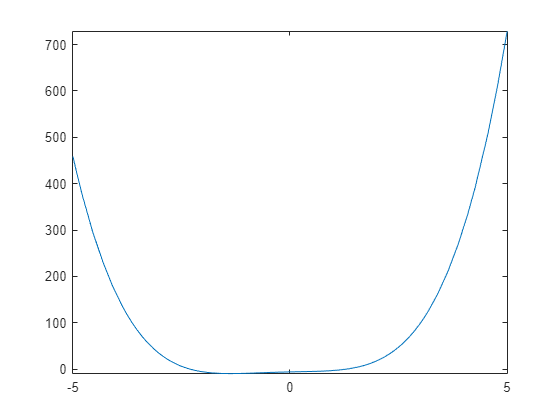

clearvars all; close all;
warning ('off', 'all')

f = @(x) x.^4 + x.^3 -x.^2 + 2*x -6;
fplot(f)

x0 = 0; r = 1.9; alpha = 2;

[left, right, iter] = expansion(f, x0, r, alpha, 100)

left = -3.8000

right = 0

iter = 1

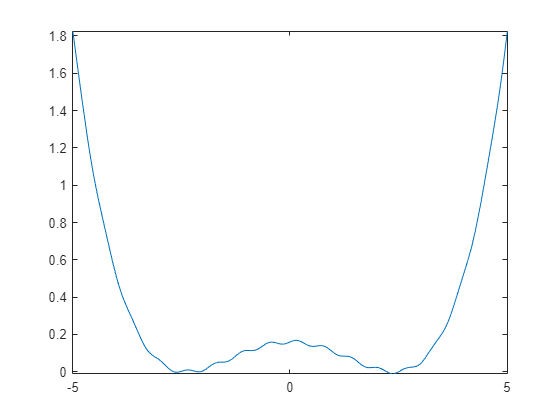


g = @(x) 0.01*sin(10*x)+(0.07*x.^2-0.4).^2;
fplot(g)

x0 = -0.5;
p = 0.1;
alpha = 1.5;

[left, right, iter] = expansion(g, x0, p, alpha, 100)

left = -3.0629

right = -1.6391

iter = 8

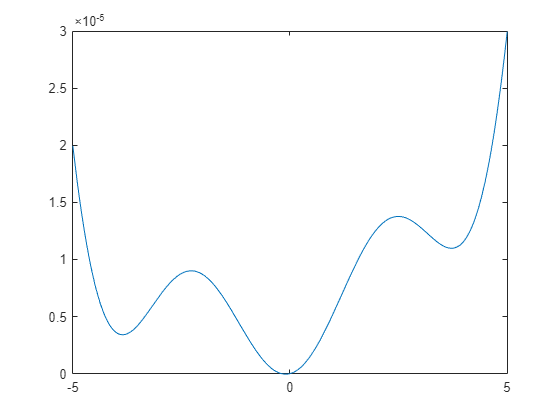


px = [-10 -5 0 5 10]; py = [0.0001 -0.1 0 0.1 -0.0001]; stopien=5;
W = polyfit(px, py, stopien);
fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;
fplot(fx)


x0=-0.5; k1=0.1; alpha=1.5;
[left, right, iter] = expansion(fx, x0, k1, alpha, 100)

left = -0.2750

right = 0.0062

iter = 4

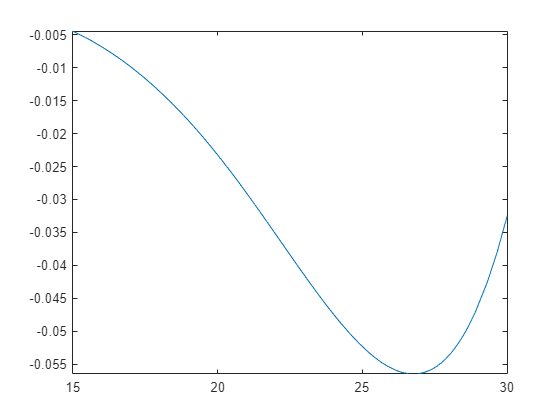


fplot(fx, [15, 30])

x0=32; k1=0.1; alpha=2;
[left, right, iter] = expansion(fx, x0, k1, alpha, 100)

left = 19.2000

right = 28.8000

iter = 7

# **Metoda kontrakcji**

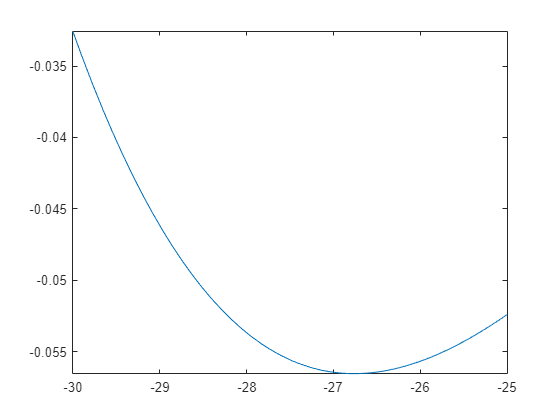

clearvars all; close all;
warning ('off', 'all')

px = [-10 -5 0 5 10]; py = [0.0001 -0.1 0 0.1 -0.0001]; stopien=5;
W = polyfit(px, py, stopien);
fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;
fplot(fx, [-30, -25])


x0 = -27.7;
x1 = -24.8;
beta = 0.9;

[left, right, xapp, yapp] = contraction(fx, x0, x1, beta, 100)

left = -27.7000

right = -25.5859

xapp = -25.7973

yapp = -0.0552


x0 = -28.4;
x1 = -27.7;
beta = 0.9;

[left, right, xapp, yapp] = contraction(fx, x0, x1, beta, 100)

left = -28.4000

right = -27.7000

xapp = -28.0500

yapp = -0.0534